% Test the evolutionary algorithm on maximizing f2(G)-f1(G)
% Run three times and display the three best graphs
% Graph Size: 15, p1 = 0.3, p2 = 0.3 (p3 = 0.4)

graphSize = 15;
p1 = 0.3;
p2 = 0.3;
bestGraphs = cell(1, 3);
bestFitValues = zeros(1, 3);
set(gcf,'Position',[100 100 260 220]);

for i = 1 : 3
    [bestGraphs{i}, bestFitValues(i)] = EA(graphSize, p1, p2);
end

% Best Graph 1
fprintf("Graph Size: " + graphSize + "\n" ...
    +"Optimal value of (f2-f1): " + bestFitValues(1) ...
    + ",  f1: " + cal_avg_path_len(bestGraphs{1}) ...
    + ",  f2: " + cal_diameter(bestGraphs{1}) + "\n");

Graph Size: 15
Optimal value of (f2-f1): 8.6667,  f1: 5.3333,  f2: 14


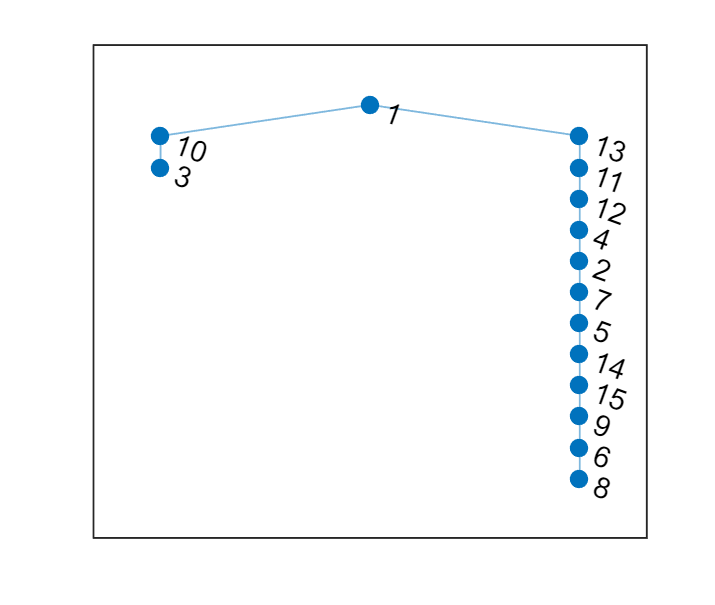

plot(graph(bestGraphs{1}));

% Best Graph 2
fprintf("Graph Size: " + graphSize + "\n" ...
    +"Optimal value of (f2-f1): " + bestFitValues(2) ...
    + ",  f1: " + cal_avg_path_len(bestGraphs{2}) ...
    + ",  f2: " + cal_diameter(bestGraphs{2}) + "\n");

Graph Size: 15
Optimal value of (f2-f1): 8.6667,  f1: 5.3333,  f2: 14


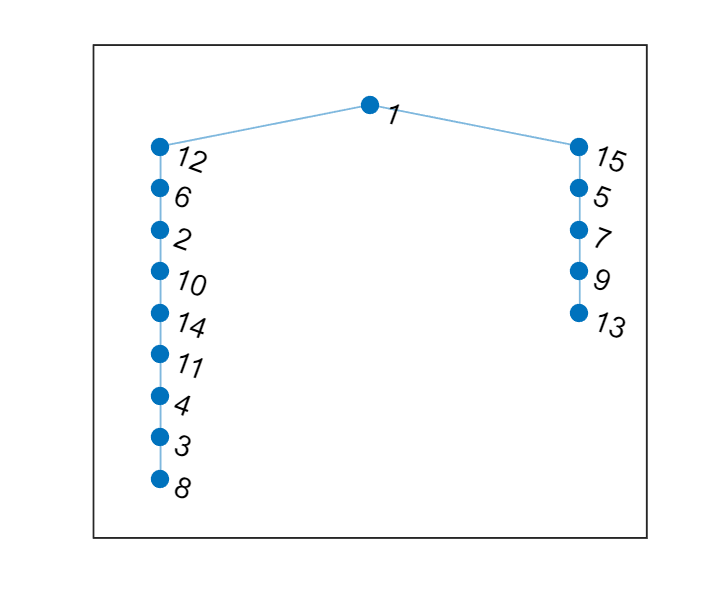

plot(graph(bestGraphs{2}));

% Best Graph 3
fprintf("Graph Size: " + graphSize + "\n" ...
    +"Optimal value of (f2-f1): " + bestFitValues(3) ...
    + ",  f1: " + cal_avg_path_len(bestGraphs{3}) ...
    + ",  f2: " + cal_diameter(bestGraphs{3}) + "\n");

Graph Size: 15
Optimal value of (f2-f1): 8.6667,  f1: 5.3333,  f2: 14


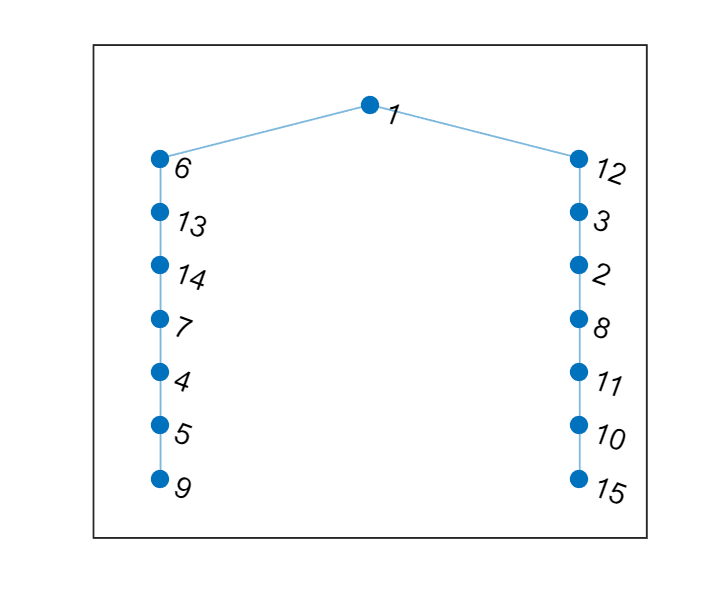

plot(graph(bestGraphs{3}));